% The function used are defined in the final part of this .m file

## global constant

    c=60;
    round=60;
    l_veh=7;
    E1=9;
    E2=13;
    E3=5;

    %parameter of ud
    N_ud=3;
    v_ud=50;
    l_ud=1000;
    mu_udo1=1600/3600;
    mu_udo2=1800/3600;
    mu_udo3=1500/3600;
    be_udo1=0.33;
    be_udo2=0.34;
    be_udo3=0.33;
    c_ud=N_ud*l_ud/l_veh;
    max_tau_ud=c_ud*l_veh/(N_ud*v_ud*c/3600*1000);

    %parameter of o1d
    N_o1d=3;
    v_o1d=60;
    l_o1d=1000;
    mu_o1du=1600/3600;
    mu_o1do3=1800/3600;
    mu_o1do2=1500/3600;
    be_o1du=0.33;
    be_o1do2=0.34;
    be_o1do3=0.33;
    c_o1d=N_o1d*l_o1d/l_veh;
    max_tau_o1d=c_o1d*l_veh/(N_o1d*v_o1d*60/3600*1000);

    % time_varying "constant"
    ae_ud=[(1800+10*E1)*ones(1,20),...
        (2100+10*E2)*ones(1,20),...
        (2300+10*E3)*ones(1,round-40)]/3600; %a_enter_ud
    ae_o1d=(2100+10*E1)*ones(1,round)/3600; %a_enter_o1d

    c_do1=zeros(1,round); 
    for i=1:1:round
        if i<=20
            c_do1(i)=40+E1;
        elseif i<=35
            c_do1(i)=40+E1-2*(i-20);
        elseif i<=45
            c_do1(i)=10+E1;
        else
            c_do1(i)=10+E1+2*(i-45);
        end
    end
    c_do1;
    c_do2=c_do1-E2*ones(1,round);
    c_do3=[(30-E3)*ones(1,30),...
        (30+E3)*ones(1,round-30)];
    c_du=[(40-E3)*ones(1,30),...
        (40+E3)*ones(1,round-30)];
    C=[ae_ud;ae_o1d;c_du;c_do1;c_do2;c_do3];
    C0=C(:,1);

## Task 3

%%%%%%%%%%%%%%%%%%%%%%Method 1: Simuannealing Optimizaiton Method

    %annealing setings

    %for annealing settings, we define tempreture and iteration times
    temperature = 100;      
    stop_temperature = 0.0001;
    %because we swtich the order of input randomly, we should run multiple
    %times for one input, here a iteration number is defined.
    iter = 20;               
    count = 0;
    golden_iter = 3;

    %initial point
    u_2_1_1 = 15*ones(1,61);
    u_2_1_2 = 45*ones(1,61);

    [final_minTTS_2_1_1,u_final_2_1_1,count0,TTS_history_2_1_1] =...
        annealing_multi(u_2_1_1,temperature,stop_temperature,round,count,iter);
    [final_minTTS_2_1_1,u_final_2_1_1,count0,temp_TTS_history_2_1_1] =...
        annealing_multi(u_final_2_1_1,temperature,stop_temperature,round,count,iter);
    TTS_history_2_1_1=[TTS_history_2_1_1,temp_TTS_history_2_1_1];
    [final_minTTS_2_1_1,u_final_2_1_1,count0,temp_TTS_history_2_1_1] =...
        annealing_multi(u_final_2_1_1,temperature,stop_temperature,round,count,iter);
    TTS_history_2_1_1=[TTS_history_2_1_1,temp_TTS_history_2_1_1];


    [final_minTTS_2_1_2,u_final_2_1_2,count0,TTS_history_2_1_2] =...
        annealing_multi(u_2_1_2,temperature,stop_temperature,round,count,iter);
    [final_minTTS_2_1_2,u_final_2_1_2,count0,temp_TTS_history_2_1_2] =...
        annealing_multi(u_final_2_1_2,temperature,stop_temperature,round,count,iter);
    TTS_history_2_1_2=[TTS_history_2_1_2,temp_TTS_history_2_1_2];
    [final_minTTS_2_1_2,u_final_2_1_2,count0,temp_TTS_history_2_1_2] =...
        annealing_multi(u_final_2_1_2,temperature,stop_temperature,round,count,iter);
    TTS_history_2_1_2=[TTS_history_2_1_2,temp_TTS_history_2_1_2];

%%%%%%%%%%%%%%%%%%%%%%Method 2: Perpendicular direction Search+Golden Section+Simuannealing Optimizaiton Method

%initial value of input
u_2_2_1 = 15*ones(1,61);
u_2_2_2 = 45*ones(1,61);

%for starting point 15s

TTS_previous_2_2_1 = TTS_calculate(u_2_2_1(1,1), u_2_2_1(1,2:61));
[u_final_2_2_1, TTS_current_2_2_1,TTS_history_2_2_1] =...
    goldensection(u_2_2_1,TTS_previous_2_2_1,golden_iter);
disp("optimal solution (15s) after perpendicular search with golden section steps:");

optimal solution (15s) after perpendicular search with golden section steps:


disp(TTS_current_2_2_1);

   7.7793e+05




[minTTS_2_2_1,u_final_2_2_1,count_2_2_1,temp_TTS_history_2_2_1] = ...
    annealing_multi(u_final_2_2_1,temperature,stop_temperature,round,count,iter);
TTS_history_2_2_1=[TTS_history_2_2_1,temp_TTS_history_2_2_1];

disp("The optimal TTS from initial point 15s:" );

The optimal TTS from initial point 15s:


disp("TTS(from 15)=");

TTS(from 15)=


disp(minTTS_2_2_1);

   7.7793e+05



disp("Corresponding U=")

Corresponding U=


disp(u_final_2_2_1);

  列 1 至 13

   22.9647   24.9788   28.0348   23.6611   28.5250   23.9029   23.5933   24.0531   27.8116   23.7277   28.1532   24.8518   25.9709

  列 14 至 26

   26.5647   24.7272   29.5642   27.0670   25.0429   24.5358   26.8732   23.5829   26.3843   29.6435   29.9298   28.7983   29.5075

  列 27 至 39

   29.7909   28.4348   30.4320   30.2828   29.2424   30.3996   30.1556   35.6638   23.7322   23.4493   22.0954   21.6535   33.0149

  列 40 至 52

   24.0652   27.7365   33.0719   31.7745   34.5765   22.0955   31.8038   31.8212   26.2642   34.7404   33.6999   34.9479   35.5551

  列 53 至 61

   36.0253   35.8262   35.7604   35.8562   35.6918   35.5404   35.7693   35.2089    9.7084




%for starting point 45s

TTS_previous_2_2_2 = TTS_calculate(u_2_2_2(1,1), u_2_2_2(1,2:61));
[u_final_2_2_2, TTS_current_2_2_2,TTS_history_2_2_2] =...
    goldensection(u_2_2_2,TTS_previous_2_2_2,golden_iter);
disp("optimal solution (45s) after perpendicular search with golden section steps:");

optimal solution (45s) after perpendicular search with golden section steps:


disp(TTS_current_2_2_2);

   7.7792e+05




[minTTS_2_2_2,u_final_2_2_2,count_2_2_2,temp_TTS_history_2_2_2] = ...
    annealing_multi(u_final_2_2_2,temperature,stop_temperature,round,count,iter);
TTS_history_2_2_2=[TTS_history_2_2_2,temp_TTS_history_2_2_2];

disp("The optimal TTS from initial point 45s:" );

The optimal TTS from initial point 45s:


disp("TTS(from 45)=");

TTS(from 45)=


disp(minTTS_2_2_2);

   7.7793e+05



disp("Corresponding U=");

Corresponding U=


disp(u_final_2_2_2);

  列 1 至 13

   46.3660   26.8905   27.6421   26.0431   29.0698   28.3186   25.3400   25.4023   29.0671   29.8904   24.2628   28.6917   27.3581

  列 14 至 26

   27.7130   26.1223   27.7401   28.8640   24.8702   28.9867   25.7447   29.2509   26.4794   29.2750   28.6657   29.1567   27.8684

  列 27 至 39

   31.0694   32.5487   33.6563   33.0111   32.3266   33.2110   33.1291   29.1828   28.5468   33.7404   32.2447   33.0861   35.1991

  列 40 至 52

   35.7978   32.7985   26.0406   31.2504   33.5824   34.6253   26.0048   34.3548   32.1197   32.7600   34.8740   34.1171   35.7037

  列 53 至 61

   35.9962   35.6773   35.7957   35.8960   35.9280   35.7170   35.7657   35.4612   34.5273



## Task 4

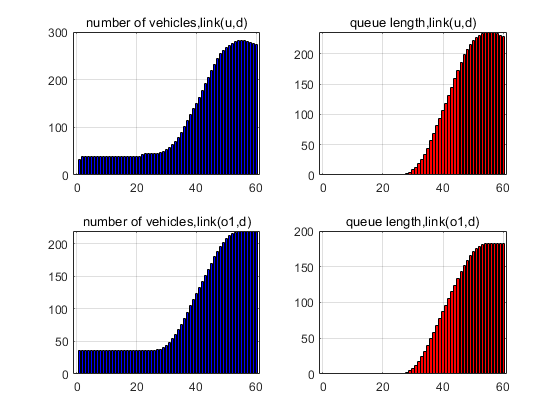

    u_4_0=30*ones(1,1);
    u_4=30*ones(1,60);
    [TTS_4,y_4,x_4,z_4,m_4,s_4,u_4] = TTS_calculate(u_4_0,u_4);

    [TTS_4_1,y_4_1,x_4_1,z_4_1,m_4_1,s_4_1,u_4_1] = TTS_calculate(u_final_2_1_1(1),u_final_2_1_1(2:end));
    [TTS_4_2,y_4_2,x_4_2,z_4_2,m_4_2,s_4_2,u_4_2] = TTS_calculate(u_final_2_1_2(1),u_final_2_1_2(2:end));    
    [TTS_4_3,y_4_3,x_4_3,z_4_3,m_4_3,s_4_3,u_4_3] = TTS_calculate(u_final_2_2_1(1),u_final_2_2_1(2:end));    
    [TTS_4_4,y_4_4,x_4_4,z_4_4,m_4_4,s_4_4,u_4_4] = TTS_calculate(u_final_2_2_2(1),u_final_2_2_2(2:end));    


    figure('Name',"Task 4 traffic situation on control， u(t)=30s")

        subplot(2,2,1)
        bar([0:1:round],x_4(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_4(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_4(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_4(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

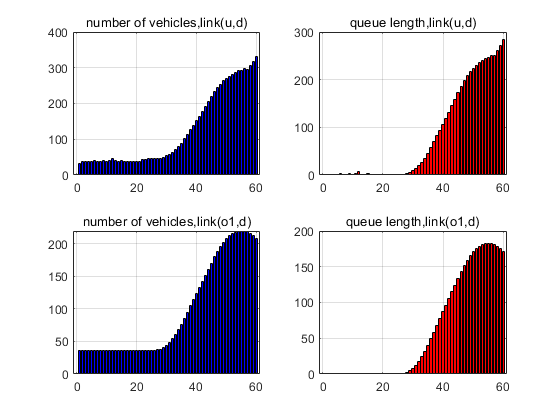


    figure('Name','Task 4 traffic situation simulannealing,15s')
        subplot(2,2,1)
        bar([0:1:round],x_4_1(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_4_1(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_4_1(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_4_1(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

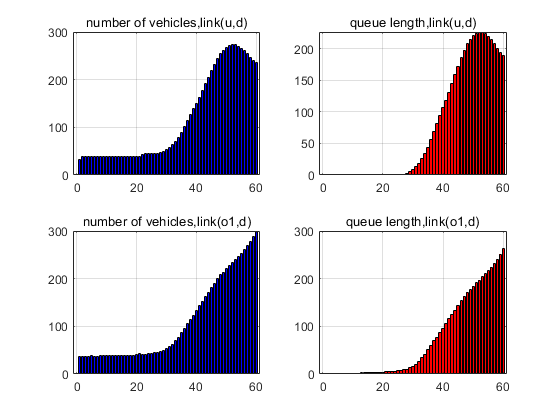

    
    figure('Name','Task 4 traffic situation simulannealing,45s')
        subplot(2,2,1)
        bar([0:1:round],x_4_2(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_4_2(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_4_2(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_4_2(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

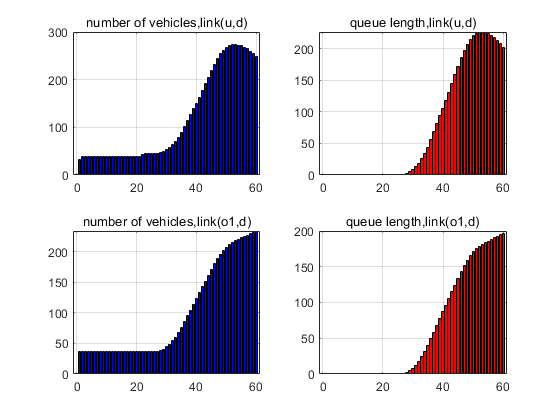


    figure('Name','Task 4 traffic situation perpendicualr,15s')
        subplot(2,2,1)
        bar([0:1:round],x_4_3(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_4_3(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_4_3(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_4_3(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

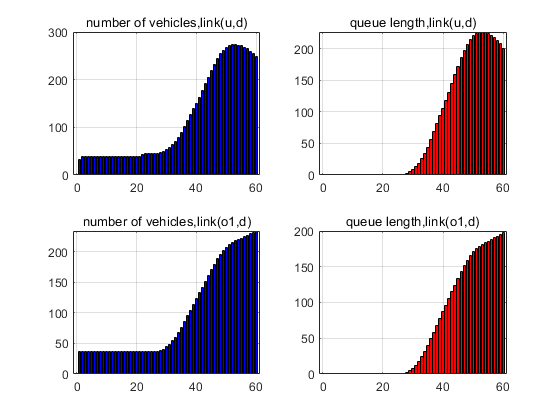

    
    figure('Name','Task 4 traffic situation perpendicualr,45s')
        subplot(2,2,1)
        bar([0:1:round],x_4_4(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_4_4(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_4_4(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_4_4(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

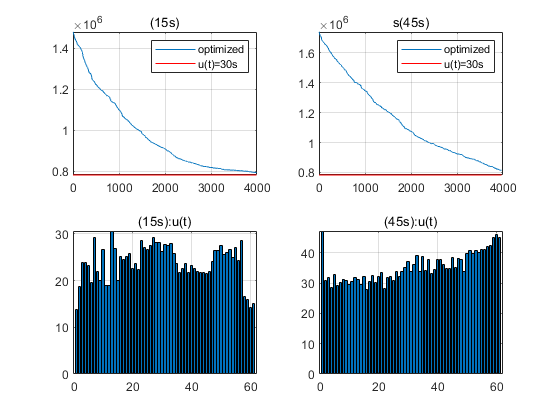

    figure('Name','Task 4 simulated annealing methods process')

        subplot(2,2,1)
        plot(TTS_history_2_1_1);
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_history_2_1_1)),'r');
        title("(15s)")
        legend('optimized','u(t)=30s')

        subplot(2,2,3)
        bar(u_final_2_1_1);
        grid on;
        title("(15s):u(t)")

        subplot(2,2,2)
        plot(TTS_history_2_1_2);
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_history_2_1_2)),'r');
        title("s(45s)")
        legend('optimized','u(t)=30s')

        subplot(2,2,4)
        bar(u_final_2_1_2);
        grid on;
        title("(45s):u(t)")

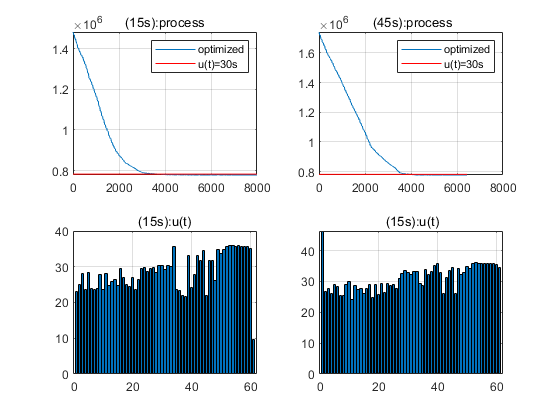



    figure('Name','Task 4 perpendicular+golden_section process')

        subplot(2,2,1)
        plot(TTS_history_2_2_1);
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_history_2_2_1)),'r');
        title("(15s):process")
        legend('optimized','u(t)=30s')

        subplot(2,2,3)
        bar(u_final_2_2_1);
        grid on;
        title("(15s):u(t)")

        subplot(2,2,2)
        plot(TTS_history_2_2_2);
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_history_2_2_2)),'r');
        title(" (45s):process")
        legend('optimized','u(t)=30s')

        subplot(2,2,4)
        bar(u_final_2_2_2);
        grid on;
        title(" (15s):u(t)")

## Task 5

    %%%genetic optimization method

        %discrete green light time set
        u_options=[15,20,25,30,35,40,45];

        %algorithm settings
        generation_round=300;
        member_number=50;
        %the exchange_position of parents
        exchange_position=30;
        %mutation probabilitTTS
        mutation_probability=0.6;
        %parents number
        parents_number=20;

        %%random initial generation

        %initial generation 0
        u_generation_5_1_1=randi(length(u_options),[1,round]);
        %u_generation=4*ones(member_number,round);
        u0_generation_5_1_1=randi(length(u_options),[member_number,1]);
        for i =2:1:member_number
            u_generation_5_1_1=[u_generation_5_1_1;randi(length(u_options),[1,round])];
        end

        [u_final_5_1_1,TTS_optimal_history_5_1_1]=...
            genetic_optimization(u0_generation_5_1_1,u_generation_5_1_1,u_options,...
                round,generation_round,member_number,mutation_probability,exchange_position,parents_number);
        TTS_optimal_5_1_1=TTS_optimal_history_5_1_1(end);
        u_final_5_1_1=(u_final_5_1_1+2)*5;
        disp("TTS of genetic+initiaal points based on random initial points 1");

TTS of genetic+initiaal points based on random initial points 1


        disp(TTS_optimal_5_1_1);

   8.3095e+05




        %%%%%%%%%initial generation 2

        %initial generation 0
        u_generation_5_1_2=randi(length(u_options),[1,round]);
        u0_generation_5_1_2=randi(length(u_options),[member_number,1]);
        for i =2:1:member_number
            u_generation_5_1_2=[u_generation_5_1_2;randi(length(u_options),[1,round])];
        end

        for i=1:1:length(u_options)
                u_generation_5_1_2(i,:)=i*ones(1,round);
                u0_generation_5_1_2(i)=i; 
        end
        [u_final_5_1_2,TTS_optimal_history_5_1_2]=...
            genetic_optimization(u0_generation_5_1_2,u_generation_5_1_2,u_options,...
                round,generation_round,member_number,mutation_probability,exchange_position,parents_number)

u_final_5_1_2 =      2     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


TTS_optimal_history_5_1_2 = 	1.0e+05 *

    7.8250    8.0161    7.9733    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250    7.8250


        TTS_optimal_5_1_2=TTS_optimal_history_5_1_2(end);
        u_final_5_1_2=(u_final_5_1_2+2)*5;
        disp("TTS of genetic+initiaal points based on random initial points 2");

TTS of genetic+initiaal points based on random initial points 2


        disp(TTS_optimal_5_1_2);

   7.8250e+05




        %%%%%%%%%initial generation based on 30s
        %initial generation 
        u_generation_5_1_3=4*ones(member_number,round);
        u0_generation_5_1_3=4*ones(member_number,1);

        for i=1:1:member_number
            for j=1:1:round
            poss=rand(1);
            if (poss<=0.1)
                u_generation_5_1_3(i,j)=randi(length(u_options),1);
            end
            end
        end

        [u_final_5_1_3,TTS_optimal_history_5_1_3]=...
            genetic_optimization(u0_generation_5_1_3,u_generation_5_1_3,u_options,...
                round,generation_round,member_number,mutation_probability,exchange_position,parents_number);
        TTS_optimal_5_1_3=TTS_optimal_history_5_1_3(end);
        u_final_5_1_3=(u_final_5_1_3+2)*5;
        disp("TTS of genetic+initiaal points based 30s:");

TTS of genetic+initiaal points based 30s:


        disp(TTS_optimal_5_1_3);

   7.8250e+05



## perpendicular search method

        %algorithms settings
        stopping_delta=1;

        %start from random intial points
        u0_5_2_1=u_options(randi(length(u_options))); % k=0
        u_5_2_1=u_options(randi(length(u_options),[1,round]));
        [u0_optimal_5_2_1,u_final_5_2_1,TTS_optimal_history_5_2_1]=perpendicular_search(u0_5_2_1,u_5_2_1,u_options,stopping_delta,round);
        TTS_optimal_5_2_1=TTS_optimal_history_5_2_1(end)

TTS_optimal_5_2_1 = 9.6776e+05

        disp("TTS of perpendicular+initiaal points based on random initial points 2");

TTS of perpendicular+initiaal points based on random initial points 2


        disp(TTS_optimal_5_2_1);

   9.6776e+05




        %start from 30s
        u0_5_2_2=4;
        u_5_2_2=30*ones(1,60);
        [u0_optimal_5_2_2,u_final_5_2_2,TTS_optimal_history_5_2_2]=perpendicular_search(u0_5_2_2,u_5_2_2,u_options,stopping_delta,round);
        TTS_optimal_5_2_2=TTS_optimal_history_5_2_2(end)

TTS_optimal_5_2_2 = 7.8133e+05

        disp("TTS of perpendicular+initiaal points based on initial points 30s");

TTS of perpendicular+initiaal points based on initial points 30s


        disp(TTS_optimal_5_2_2);

   7.8133e+05



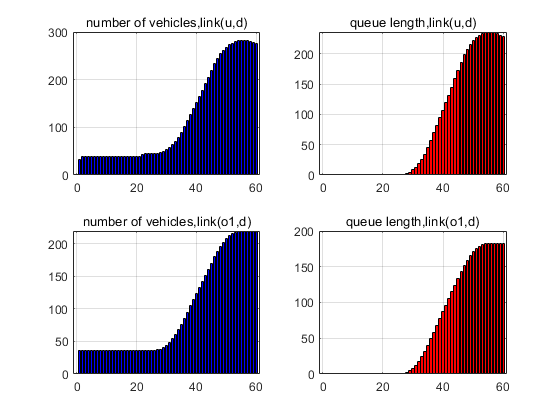



    [TTS_5_1,y_5_1,x_5_1,z_5_1,m_5_1,s_5_1,u_5_1] = TTS_calculate(u_final_5_1_3(1),u_final_5_1_3(2:end));
    [TTS_5_2,y_5_2,x_5_2,z_5_2,m_5_2,s_5_2,u_5_2] = TTS_calculate(u_final_5_2_2(1),u_final_5_2_2(2:end)); 

    figure('Name','Task 5 traffic situation genetic')
        subplot(2,2,1)
        bar([0:1:round],x_5_1(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_5_1(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_5_1(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_5_1(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

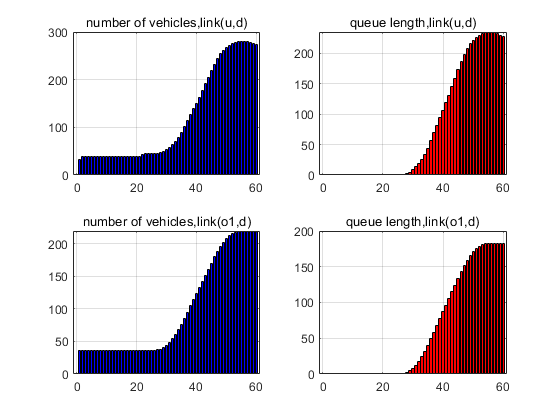

    
    figure('Name','Task 5 traffic situation perpendicular')
        subplot(2,2,1)
        bar([0:1:round],x_5_2(1,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(u,d)")

        subplot(2,2,3)
        bar([0:1:round],x_5_2(2,:),'b');
        hold on;
        grid on;
        title("number of vehicles,link(o1,d)")

        subplot(2,2,2)
        bar([0:1:round],s_5_2(3,:),'r');
        hold on;
        grid on;
        title("queue length,link(u,d)")

        subplot(2,2,4)
        bar([0:1:round],s_5_2(4,:),'r');
        hold on;
        grid on;
        title("queue length,link(o1,d)")

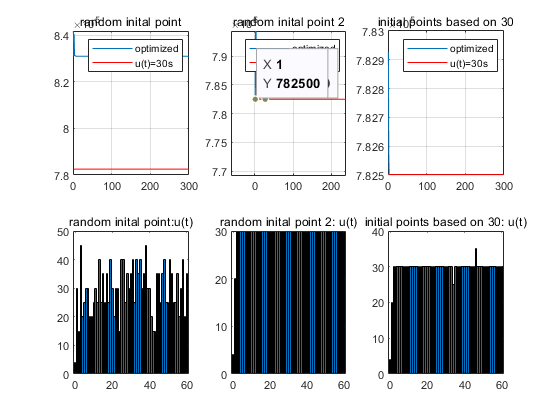


    figure('Name','Task 5 Genetic Problem')
        subplot(2,3,1)
        plot(TTS_optimal_history_5_1_1)
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_optimal_history_5_1_1)),'r');
        title("random inital point")
        legend('optimized','u(t)=30s')

        subplot(2,3,4)
        bar([0:1:round],[4,u_final_5_1_1])
        title("random inital point:u(t)")
        

        subplot(2,3,2)
        plot(TTS_optimal_history_5_1_2)
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_optimal_history_5_1_2)),'r');
        title("random inital point 2")
        legend('optimized','u(t)=30s')

        subplot(2,3,5)
        bar([0:1:round],[4,u_final_5_1_2])
        title("random inital point 2: u(t)")

        subplot(2,3,3)
        plot(TTS_optimal_history_5_1_3)
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_optimal_history_5_1_3)),'r');
        title("initial points based on 30")
        legend('optimized','u(t)=30s')

        subplot(2,3,6)
        bar([0:1:round],[4,u_final_5_1_3])
        title("initial points based on 30: u(t)")

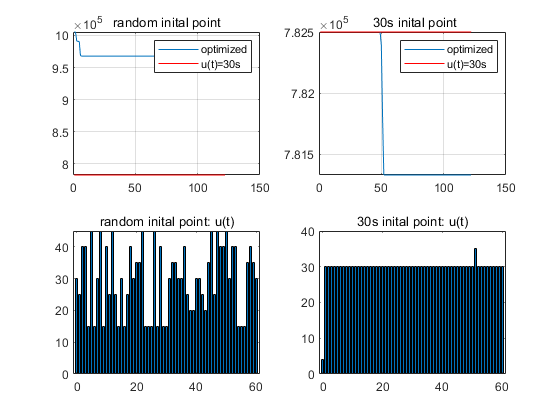


    figure('Name','Task 5 perpendicular search method')

        subplot(2,2,1)
        plot(TTS_optimal_history_5_2_1)
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_optimal_history_5_2_1)),'r');
        title("random inital point")
        legend('optimized','u(t)=30s')

        subplot(2,2,3)
        bar([0:1:round],[u0_optimal_5_2_1, u_final_5_2_1]);
        title("random inital point: u(t)")

        subplot(2,2,2)
        plot(TTS_optimal_history_5_2_2)
        grid on;
        hold on;
        plot(TTS_4*ones(1,length(TTS_optimal_history_5_2_2)),'r');
        title(" 30s inital point")
        legend('optimized','u(t)=30s')

        subplot(2,2,4)
        bar([0:1:round],[u0_optimal_5_2_2, u_final_5_2_2]);
        title("30s inital point: u(t)")

## function TTS_calculate in order to calculate y

function [TTS,y,x,z,m,s,u] = TTS_calculate(u0,u)
    % calculate the sum of TTS based on input u
    %%%%%%%%%%%%%%%%%%%%%%constant%%%%%%%%%%%%%%%%%%%%%%%%%%
    c=60;
    round=60;
    l_veh=7;

    E1=9;
    E2=13;
    E3=5;

    %parameter of ud

    N_ud=3;
    v_ud=50;
    l_ud=1000;

    mu_udo1=1600/3600;
    mu_udo2=1800/3600;
    mu_udo3=1500/3600;

    be_udo1=0.33;
    be_udo2=0.34;
    be_udo3=0.33;

    c_ud=N_ud*l_ud/l_veh;

    max_tau_ud=c_ud*l_veh/(N_ud*v_ud*c/3600*1000);

    %parameter of o1d

    N_o1d=3;
    v_o1d=60;
    l_o1d=1000;

    mu_o1du=1600/3600;
    mu_o1do3=1800/3600;
    mu_o1do2=1500/3600;

    be_o1du=0.33;
    be_o1do2=0.34;
    be_o1do3=0.33;

    c_o1d=N_o1d*l_o1d/l_veh;

    max_tau_o1d=c_o1d*l_veh/(N_o1d*v_o1d*60/3600*1000);


    % time_varying "constant"
    ae_ud=[(1800+10*E1)*ones(1,20),...
        (2100+10*E2)*ones(1,20),...
        (2300+10*E3)*ones(1,round-40)]/3600; %a_enter_ud

    ae_o1d=(2100+10*E1)*ones(1,round)/3600; %a_enter_o1d

    c_do1=zeros(1,round); 
    for i=1:1:round
        if i<=20
            c_do1(i)=40+E1;
        elseif i<=35
            c_do1(i)=40+E1-2*(i-20);
        elseif i<=45
            c_do1(i)=10+E1;
        else
            c_do1(i)=10+E1+2*(i-45);
        end
    end
    c_do1;

    c_do2=c_do1-E2*ones(1,round);

    c_do3=[(30-E3)*ones(1,30),...
        (30+E3)*ones(1,round-30)];

    c_du=[(40-E3)*ones(1,30),...
        (40+E3)*ones(1,round-30)];

    C=[ae_ud;ae_o1d;c_du;c_do1;c_do2;c_do3];

    C0=C(:,1);

## states defination

    %total states
    x=zeros(10,1);  % states x
    z=zeros(6,1);   % the time-varying "constant"
    % u=30;   %input
    m=zeros(6,1); % a^leave, the minimize function
    s=zeros(4,1); %states i

    tau=zeros(0,1);
    lam=zeros(2,1); %first line for ud, second line for o1d

    y=zeros(1,1);

    %current states(initial)
    temp_x=zeros(10,1);  % states x
    temp_z=zeros(6,1);   % the time-varying "constant"
    temp_u=u(1);   %input
    temp_m=zeros(6,1); % a^leave, the minimize function
    temp_s=zeros(4,1); %states i

    temp_tau=zeros(2,1); %first line for ud, second line for o1d
    temp_lam=zeros(2,1); %first line for ud, second line for o1d

    temp_y=zeros(1,1);

    %(k-1)states
    prev_x=zeros(10,1);  % states x
    prev_z=zeros(6,1);   % the time-varying "constant"
    prev_u=30;   %input
    prev_m=zeros(6,1); % a^leave, the minimize function
    prev_s=zeros(4,1); % states i

    prev_lam=zeros(2,1); %first line for ud, second line for o1d

    prev_y=zeros(1,1);

    %k-2 states
    prev_prev_z=zeros(6,1); % the time-varying "constant"

## initial variables(k=0)

    %initial z
    temp_z=C0;

    %initial u
    temp_u=u0;

    %initial for lam & tau
    temp_tau(1)=floor((c_ud-temp_s(3))*l_veh/ ...
        (N_ud*v_ud*c/3600*1000));
    temp_lam(1)=mod((c_ud-temp_s(3))*l_veh/ ...
        (N_ud*v_ud/3600*1000),c);

    temp_tau(2)=floor((c_o1d-temp_s(4))*l_veh/ ...
        (N_o1d*v_o1d*c/3600*1000));
    temp_lam(2)=mod((c_o1d-temp_s(4))*l_veh/ ...
        (N_o1d*v_o1d/3600*1000),c);

    %initial for aa_ud
    if temp_tau(1)==0
        temp_x(3)=(c-temp_lam(1))/c*temp_z(1)+temp_lam(1)/c*prev_z(1);

    elseif temp_tau(1)==1
        temp_x(3)=(c-temp_lam(1))/c*prev_z(1)+temp_lam(1)/c*prev_prev_z(1);

    else
        "k-3 appear!";

    end

    %initial for aa_o1d
    if temp_tau(2)==0
        temp_x(4)=(c-temp_lam(2))/c*temp_z(2)+temp_lam(2)/c*prev_z(2);

    elseif temp_tau(1)==1
        temp_x(4)=(c-temp_lam(2))/c*prev_z(2)+temp_lam(2)/c*prev_prev_z(2);

    else
        "k-3 appear!";

    end

    %initial al (mins)
    temp_m(1)=min([mu_udo1*temp_u/c,...
        temp_x(5)/c+be_udo1*temp_x(3),...
        temp_z(4)/c/2]);
    temp_m(2)=min([mu_udo2*temp_u/c,...
        temp_x(6)/c+be_udo2*temp_x(3),...
        temp_z(5)/c/2]);
    temp_m(3)=min([mu_udo3*c/c,...
        temp_x(7)/c+be_udo3*temp_x(3),...
        temp_z(6)/c/2]);
    temp_m(4)=min([mu_o1du*c/c,...
        temp_x(8)/c+be_o1du*temp_x(4),...
        temp_z(3)/c/2]);
    temp_m(5)=min([mu_o1do2*(c-temp_u)/c,...
        temp_x(9)/c+be_o1do2*temp_x(4),...
        temp_z(5)/c/2]);
    temp_m(6)=min([mu_o1do3*(c-temp_u)/c,...
        temp_x(10)/c+be_o1do3*temp_x(4),...
        temp_z(6)/c/2]);

    temp_s(1)=temp_m(1)+temp_m(2)+temp_m(3);
    temp_s(2)=temp_m(4)+temp_m(5)+temp_m(6);


    x=temp_x;
    y=temp_y;

    prev_u=temp_u;
    prev_x=temp_x;
    prev_y=temp_y;
    prev_z=temp_z;
    prev_s=temp_s;
    prev_mt=temp_m;
    prev_tau=temp_tau;
    prev_lam=temp_lam;

## iteration

    for k=1:1:60

        temp_z=C(:,k);
        temp_u=u(k);

        % iteration for n
        temp_x(1)=prev_x(1)+c*(prev_z(1)-prev_s(1));
        temp_x(2)=prev_x(2)+c*(prev_z(2)-prev_s(2));

        %iteration for y
        temp_y=c*(temp_x(1)+temp_x(2));

        %iteration for q
        temp_x(5)=prev_x(5)+(be_udo1*prev_x(3)-prev_m(1))*c;
    %     prev_x(3)
    %     prev_m(1)
    %     be_udo1*prev_x(3)-prev_m(1)
        temp_x(6)=prev_x(6)+(be_udo2*prev_x(3)-prev_m(2))*c;
        temp_x(7)=prev_x(7)+(be_udo3*prev_x(3)-prev_m(3))*c;
        temp_x(8)=prev_x(8)+(be_o1du*prev_x(4)-prev_m(4))*c;
        temp_x(9)=prev_x(9)+(be_o1do2*prev_x(4)-prev_m(5))*c;
        temp_x(10)=prev_x(10)+(be_o1do3*prev_x(4)-prev_m(6))*c;

        %iteration for sum q
        temp_s(3)=temp_x(5)+temp_x(6)+temp_x(7);
        temp_s(4)=temp_x(8)+temp_x(9)+temp_x(10);

        %iteration for lam & tau 
        temp_tau(1)=floor((c_ud-temp_s(3))*l_veh/ ...
            (N_ud*v_ud*c/3600*1000));
        temp_lam(1)=mod((c_ud-temp_s(3))*l_veh/ ...
            (N_ud*v_ud/3600*1000),c);

        temp_tau(2)=floor((c_o1d-temp_s(4))*l_veh/ ...
            (N_o1d*v_o1d*c/3600*1000));
        temp_lam(2)=mod((c_o1d-temp_s(4))*l_veh/ ...
            (N_o1d*v_o1d/3600*1000),c);

        %iteration for aa_ud
        if temp_tau(1)==0
            temp_x(3)=(c-temp_lam(1))/c*temp_z(1)+temp_lam(1)/c*prev_z(1);       
        elseif temp_tau(1)==1
            temp_x(3)=(c-temp_lam(1))/c*prev_z(1)+temp_lam(1)/c*prev_prev_z(1);       
        else
            "k-3 appear!";       
        end

        %iteration for aa_o1d
        if temp_tau(2)==0
            temp_x(4)=(c-temp_lam(2))/c*temp_z(2)+temp_lam(2)/c*prev_z(2);   
        elseif temp_tau(1)==1
            temp_x(4)=(c-temp_lam(2))/c*prev_z(2)+temp_lam(2)/c*prev_prev_z(2);   
        else
            "k-3 appear!";       
        end

        %iteration al (mins)
        temp_m(1)=min([mu_udo1*temp_u/c,...
            temp_x(5)/c+be_udo1*temp_x(3),...
            temp_z(4)/c/2]);
        temp_m(2)=min([mu_udo2*temp_u/c,...
            temp_x(6)/c+be_udo2*temp_x(3),...
            temp_z(5)/c/2]);
        temp_m(3)=min([mu_udo3*c/c,...
            temp_x(7)/c+be_udo3*temp_x(3),...
            temp_z(6)/c/2]);
        temp_m(4)=min([mu_o1du*c/c,...
            temp_x(8)/c+be_o1du*temp_x(4),...
            temp_z(3)/c/2]);
        temp_m(5)=min([mu_o1do2*(c-temp_u)/c,...
            temp_x(9)/c+be_o1do2*temp_x(4),...
            temp_z(5)/c/2]);
        temp_m(6)=min([mu_o1do3*(c-temp_u)/c,...
            temp_x(10)/c+be_o1do3*temp_x(4),...
            temp_z(6)/c/2]);

        temp_s(1)=temp_m(1)+temp_m(2)+temp_m(3);
        temp_s(2)=temp_m(4)+temp_m(5)+temp_m(6);

        %contanate 
        x=[x,temp_x];
        z=[z,temp_z];
        m=[m,temp_m];
        s=[s,temp_s];    
        u=[u,temp_u];   
        y=[y,temp_y]; 

        %update, prepare for k+1
        prev_u=temp_u;
        prev_prev_z=prev_z;
        prev_y=temp_y;
        prev_x=temp_x;
        prev_m=temp_m;
        prev_z=temp_z;
        prev_s=temp_s;
        prev_tau=temp_tau;
        prev_lam=temp_lam;        

    end
    TTS=sum(y);

    if nargout==1
        TTS;
    end

end

## function for simulannealing method

    function u_new = turbulent(u_old,n)
        p1 = floor(1+n*rand());
        p2 = floor(1+n*rand());
        
        while p1==p2
            p1 = floor(1+n*rand());
            p2 = floor(1+n*rand());    
        end
        
        tmp = u_old(p1);
        u_old(p1) = u_old(p2)+2*rand()-1;
        u_old(p2) = tmp+2*rand()-1;    
        
        u_new = u_old;
    end

    %when we obtain a new solution by slighty randomly swtich the order of
    %previous solution, we can compute new TTS by following function
    function [u1,TTS] = TTS_campare(TTS,TTS1,TTS2,temperature,u1,u2)
        %TTS1 is the old solution.
        delta_TTS = TTS2-TTS1;
        if delta_TTS < 0
            u1 = u2;
            TTS = [TTS TTS2];
        else
                if exp(-delta_TTS/temperature)>rand() 
                    u1 = u2;  
                    TTS = [TTS TTS2];
                end
            TTS = [TTS TTS1];
        end    
    end

    %we can try different inputs to check whether the result we got is the
    %loacol optimization or not.
    function [TTS_optimal,count,u1,TTS_history] = annealing(u0,temperature,stop_temperature,round)
        count = 1;
        u1 = u0;
        TTS_history = [];
        while temperature > stop_temperature

            TTS1 = TTS_calculate(u1(1,1),u1(1,2:60));
            u2 = turbulent(u1,round);
            TTS2 = TTS_calculate(u2(1,1),u2(1,2:60));

            [u1,TTS_history] = TTS_campare(TTS_history,TTS1,TTS2,temperature,u1,u2);

            count = count + 1;
            if rem(count,10) == 0
                temperature = temperature*0.9;        
            end    
        end
        TTS_optimal = TTS_history(end);   
        if nargout==1
            TTS_optimal;
        end
    end

    %we can run annealing multiple times to eliminate the influence of
    %random solution selection
    function [TTS_final,u_final,count,TTS_history] = annealing_multi(u0,temperature,stop_temperature,round,count,iter)

        [TTS_final,count,u_final,TTS_history] = annealing(u0,temperature,stop_temperature,round);  
        for i = 1:1:iter
            [final_TTS_u0_1,temp_count,temp_u,temp_TTS_history] = annealing(u0,temperature,stop_temperature,round);
            count = count + temp_count;
            if final_TTS_u0_1<TTS_final
            TTS_final = final_TTS_u0_1; 
            TTS_history=temp_TTS_history;
            u_final = temp_u;
            end
        end
    end

## functions for golden section method

    %golden section is to calculate the local minimum within a given interval, the output can be modified input can corresponding TTS.
    function [unew, TTS_current] = golden_section_once(k,u0)

        step = 2*rand()-1;    
        while ((u0(k) + step) >= 45) && ((u0(k) + step) <= 15)
            step = 2*rand()-1;        
        end
    
        lb = u0(k);
        ub = u0(k) + step;
        
        tol = 1.0e-6;
        % if nargin < 4; tol = 1.0e-6; end
        
        nIter = ceil(-2.078087*log(tol/abs(lb-ub)));
        golden1 = 0.618033989;
        golden2 = 1 - golden1;
        % First telescoping
        x1 = golden1*ub + golden2*lb;
        x2 = golden2*ub + golden1*lb;
        
        u_1 = u0; u_1(1,k) = x1;
        u_2 = u0; u_2(1,k) = x2;
        u_lb = u0;u_lb(1,k) = lb;
        u_ub = u0;u_ub(1,k) = ub;
        
        f1 = TTS_calculate(u_1(1,1), u_1(1,2:61));
        f2 = TTS_calculate(u_2(1,1), u_1(1,2:61));
        flb = TTS_calculate(u_lb(1,1), u_lb(1,2:61));
        fub = TTS_calculate(u_ub(1,1), u_ub(1,2:61));
        
        % 
        for i =1:1:nIter
            if f1 > f2
                lb = x1; x1 = x2; f1 = f2;
                x2 = golden2*lb + golden1*ub;
                u_2(1,k) = x2;
                f2 = TTS_calculate(u_2(1,1), u_1(1,2:61));
                unew = u_2;
                TTS_current = f2;
            elseif f1<f2
                ub = x2; x2 = x1; f2 = f1;
                x1 = golden1*lb + golden2*ub;
                u_1(1,k) = x1;
                f1 = TTS_calculate(u_2(1,1), u_1(1,2:61));
                unew = u_1;
                TTS_current = f1;
            else
                unew = u_ub;
                TTS_current = fub;
            end
        end    
    end

    %we must be carfeul when dealing with this function's stop certerion, we should count how many times we observe the same output
    %when the number is large enough, we stop the searching. 
    %haven't finished yet
    function [u_output,TTS_current,TTS_optimal_history] = goldensection(u_input,TTS_previous0,golden_iter)
        count_number = 0;
        TTS_previous = TTS_previous0;
        TTS_previous_round = TTS_previous;
        TTS_optimal_history=[];
        while count_number < golden_iter
            for i = 1:1:61
                [u_output, TTS_current] = golden_section_once(i,u_input);
                if(TTS_current > TTS_previous)
                else
                    u_input = u_output;
                    TTS_previous = TTS_current;
                end 
                TTS_optimal_history=[TTS_optimal_history,TTS_current];
            end
            if TTS_current == TTS_previous_round
                count_number = count_number + 1;
            end
            TTS_previous_round = TTS_current;
        end
    end

## function for genetic optimization method

function [u_optimal,TTS_min_history]=genetic_optimization(u0_generation,u_generation,u_options,...
    round,generation_round,member_number,mutation_probability,exchange_position,parents_number)
    %u_optimal for the optimal u(k),TTS_min_history for the TTS history

    u=ones(1,round);
    TTS_generation=ones(member_number,1);
    TTS_min=[];
    for i=1:1:generation_round
        for j=1:1:member_number
            u0=u_options(u0_generation(j));
            for k=1:1:round
                u(k)=u_options(u_generation(j,k));
            end
            TTS(j) = TTS_calculate(u0,u);
        end
        %sort TTS to find better parents
        sorted_TTS=sort(TTS);
        
        %specified better parents
        parents_position=find(TTS<=sorted_TTS(parents_number),parents_number);
        
        %calculate weight of parents
        w=zeros(1,member_number);
        w(parents_position)=sum(TTS(parents_position))./TTS(parents_position);
        w=w/sum(w);
        
        TTS_min=[TTS_min,min(TTS)];
        pos=find(TTS==min(TTS));
        u_optimal=u_generation(pos(1),:);
        
        %generation children
        children=[];
        for t=1:1:member_number/2
            parent_1=randsample([1:1:member_number],1,true,w);
            parent_2=randsample([1:1:member_number],1,true,w);
            
            %exchange
            child_1=[u_generation(parent_1,1:exchange_position),...
                u_generation(parent_2,exchange_position+1:end)];
            child_2=[u_generation(parent_2,1:exchange_position),...
                u_generation(parent_1,exchange_position+1:end)];
            
            %mutation
            for b=1:1:length(round)
                prob_1=rand(1);
                prob_2=rand(2);
                if (prob_1<=mutation_probability)
                    child_1(b)=randi(length(u_options));
                end
                if (prob_2<=mutation_probability)
                    child_2(b)=randi(length(u_options));
                end
            end
            
            %%add children to new generation
            children=[children;child_1;child_2];
                 
        end
        u_generation=children;
    end
    u_generation;
    TTS_min_history=TTS_min;
end

## function for perpendicular search method

function [u0_optimal,u_optimal,TTS_min_history]=perpendicular_search(u0,u,u_options,stopping_delta,round)
    %iteration
    delta=2;
    u0_optimal=u0;
    u_optimal=u;
    TTS=[];
    TTS_optimal = TTS_calculate(u0,u);
    while (delta>=stopping_delta)
    % for r=1:1:5
        for k = 1:1:round+1
            %choose perpendicular search direction
            temp_u=u;
            direction(k)=1;
            
            %choose the step
            if k==1
               for i= 1:1:length(u_options)
                    temp_u0=u_options(i);
                    [temp_TTS] = TTS_calculate(temp_u0,temp_u);
                    
                    if temp_TTS <TTS_optimal
                        u0_optimal=temp_u0;
                        TTS_optimal=temp_TTS;
                    end        
                end         
                TTS=[TTS,TTS_optimal];
            else
                for i= 1:1:length(u_options)
                    temp_u(k-1)=u_options(i);
                    temp_TTS = TTS_calculate(temp_u0,temp_u);
                    if temp_TTS <TTS_optimal
                        u_optimal=temp_u;
                        TTS_optimal=temp_TTS;
                    end    
                end
                TTS=[TTS,TTS_optimal];
            end
            direction(k)=0;
        end
        delta=abs(TTS(end)-TTS(end-round));
    end
    TTS_min_history=TTS;
end